load("total_biomass_16.txt")
load("total_biomass_32.txt")
%load("total_biomass_M8_39.txt")
%load("total_biomass_M16.txt")
%load("total_biomass_Noise0_000001.txt")
%load("total_biomass_M32.txt")

f=plot(0.05*total_biomass_16(1:5000,1)/24,total_biomass_16(1:5000,2),LineWidth=2)

f =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0021 0.0042 0.0063 0.0083 0.0104 0.0125 0.0146 0.0167 0.0187 0.0208 0.0229 0.0250 0.0271 0.0292 0.0312 0.0333 0.0354 0.0375 0.0396 0.0417 0.0438 0.0458 0.0479 0.0500 0.0521 0.0542 0.0563 0.0583 0.0604 0.0625 0.0646 0.0667 … ]
              YData: [1.2104e-04 1.2392e-04 1.2688e-04 1.2990e-04 1.3300e-04 1.3617e-04 1.3941e-04 1.4273e-04 1.4599e-04 1.4882e-04 1.5137e-04 1.5374e-04 1.5597e-04 1.5811e-04 1.6016e-04 1.6214e-04 1.6407e-04 1.6595e-04 1.6779e-04 1.6960e-04 … ]

  Show all properties


hold on
f=plot(0.05*total_biomass_32(1:5000,1)/24,total_biomass_32(1:5000,2),LineWidth=2)

f =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0021 0.0042 0.0063 0.0083 0.0104 0.0125 0.0146 0.0167 0.0187 0.0208 0.0229 0.0250 0.0271 0.0292 0.0312 0.0333 0.0354 0.0375 0.0396 0.0417 0.0438 0.0458 0.0479 0.0500 0.0521 0.0542 0.0563 0.0583 0.0604 0.0625 0.0646 0.0667 … ]
              YData: [1.2104e-04 1.2287e-04 1.2474e-04 1.2663e-04 1.2855e-04 1.3050e-04 1.3248e-04 1.3448e-04 1.3647e-04 1.3812e-04 1.3953e-04 1.4081e-04 1.4199e-04 1.4309e-04 1.4412e-04 1.4509e-04 1.4601e-04 1.4690e-04 1.4775e-04 1.4856e-04 … ]

  Show all properties


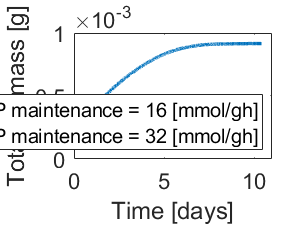

ax =   Axes with properties:

             XLim: [0 11]
             YLim: [0 1.0000e-03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1259 0.7750 0.7991]
            Units: 'normalized'

  Show all properties


hold on
%f=plot(0.05*total_biomass_Noise0_000001(1:4001,1)/24,total_biomass_Noise0_000001(1:4001,2),LineWidth=1.5)
%hold on
%f=plot(0.05*total_biomass_M8_39(1:5000,1)/24,total_biomass_M8_39(1:5000,2),LineWidth=1.5)
%hold on
%f=plot(0.05*total_biomass_M16(1:5000,1)/24,total_biomass_M16(1:5000,2),LineWidth=1.5)
%hold on
%f=plot(0.05*total_biomass_M32(1:5000,1)/24,total_biomass_M32(1:5000,2),LineWidth=1.5)
%hold on

xlim([0,11])
ylim([0,1.0e-3])
xlabel('Time [days]')
ylabel('Total biomass [g]')
legend('ATP maintenance = 16 [mmol/gh]','ATP maintenance = 32 [mmol/gh]','Location','southeast')
ax=gca;
ax.FontSize=13

exportgraphics(gcf,'total_biomass.png','Resolution', 300)